初版：2022年1月8日

# シミュレーション　講義ノート No.6

#### 藤原　哉

#### 農林中央金庫

### 1.  アメリカンオプションとは

　アメリカンオプションとは満期までの任意の時点で権利行使が可能なオプションの総称である。任意ではなく決められた時点（例：半年ごと）で権利行使可能なオプションもあり、バミューダンオプションと呼ばれる。アメリカンオプションの数値計算方法を用いてバミューダンオプションを評価することができるため、この講義ではバミューダンオプションも含めてアメリカンオプションと呼ぶことにする。

　アメリカンオプションはオプション価値が最大となるように権利行使されることから、オプション価値 $V_t$は次のように定式化される。


$$\frac{V_t}{B_t} = \sup_{\tau \in [t,T]} \mathbb{E} \left[ \frac{{\rm payoff}(X_{\tau})}{B_{\tau}} \right] \\ B_t = {\rm e}^{ \int_0^{t} r_s {\rm d} s}$$


$X_t$はオプションの原資産、 $T$はオプション満期、 $r_t$は短期金利である。

$\tau$は最適権利行使時刻と呼ばれることが多い。 $\tau$は確率変数であるが、直接評価することは難しい。

  数値計算で評価するときには、時間を離散化 ($t = t_0, t_1, \cdots,t_i,\cdots,t_N = T$)して、以下のように満期からバックワードに解くことが多い。


$$V_{t_N} = {\rm payoff}(X_{t_N}) \\ V_{t_i} = \max\left[{\rm payoff}(X_{t_i}), B_{t_{i}}\mathbb{E}\left[\left.  \frac{V_{t_{i+1}}}{B_{t_{i+1}}}\right\vert X_{t_i}\right] \right]$$


この方法では条件付期待値 $B_{t_i}\mathbb{E}\left[ \left. \frac{V_{t_{i+1}}}{B_{t_{i+1}}} \right\vert X_{t_i}  \right]$の評価がキーとなる。$B_{t_i}\mathbb{E}\left[ \left. \frac{V_{t_{i+1}}}{B_{t_{i+1}}} \right\vert X_{t_i}  \right]$は $t_i$で権利行使をしないときのオプション価値となるので、継続価値（続行価値）と呼ばれる。

### 2. 二項ツリーでの条件付期待値の評価

  条件付期待値の計算の最も簡単な方法は二項ツリーでの各ノードでのオプション価格である。

時点 $t_0$での原資産価格を $S_0$、上昇率を $u$、下降率を $d$とすると二項ツリーは下図のようになる。図での○がノードを表している。

各ノードでの原資産価格は $S_{t_i}(j) = S_0 u^{i-i}d^j, \ i = 0,\cdots, N, \ j=0,\cdots,i$と表される。

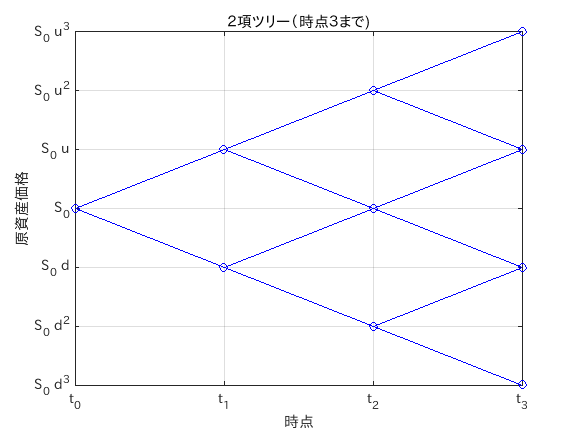

clear;

[ts,vs] = mkDataForBinaryTreeGraph();
nfig = 1;
figure(nfig);plot(ts,vs,'b-o');title('２項ツリー（時点３まで)'); grid;
xlabel('時点'); xticks([0,1,2,3]); xticklabels({'t_0','t_1','t_2','t_3'}); 
ylabel('原資産価格'); yticklabels({'S_0 d^3','S_0 d^2','S_0 d', 'S_0', 'S_0 u', 'S_0 u^2','S_0 u^3'});

具体的に計算するために上昇率、下降率を以下のように定める。時間間隔は等間隔として $\Delta t = t_{i+1}-t_i$とする。


$$u = {\rm e}^{\left(r - \frac{1}{2}\sigma^2\right)\Delta t + \sigma \sqrt{\Delta t}} \\ d = {\rm e}^{\left(r - \frac{1}{2}\sigma^2\right)\Delta t - \sigma \sqrt{\Delta t}}$$


ただし、 $r,\sigma$は金利と変動率を表すパラメータである。　

このときリスク中立確率での上昇確率ｑは


$$q = \frac{{\rm e}^{r\Delta t}-d}{u-d} = \frac{{\rm e}^{\frac{1}{2}\sigma^2\Delta t}-{\rm e}^{-\sigma \sqrt{\Delta t}}}{{\rm e}^{\sigma \sqrt{\Delta t}}-{\rm e}^{-\sigma\sqrt{\Delta}}}$$


である。

二項ツリーでのアメリカンオプションの評価は次のようになる。

- 満期 $t_N$での各ノードのオプションの値は $V_{t_N}(j) = {\rm payoff}\left(S_0 u^{N-j} d^j\right),\ j =0,\cdots,N$となる。

- 時点 $t_i < t_N$での各ノードの権利行使前のオプションの値は $V^{pre}_{t_i}(j) = {\rm e}^{-r\Delta t} \left[ q V_{t_{i+1}}(j) + (1-q) V_{t_{i+1}}(j+1) \right]$

- 権利行使を考慮したオプションの値は $V_{t_i}(j) = \max\left[{\rm payoff}\left(S_0 u^{i-j}d^j \right), V_{t_i}^{pre}(j) \right], \ j=0,\cdots,i$、 ただし、$t_i$が権利行使時点ではない場合は $V_{t_i}(j) = V_{t_i}^{pre}(j)$

２番めのステップでの $V_{t_i}^{pre}(j)$が条件付期待値計算、 $V_{t_i}^{pre}(j) = \mathbb{E}\left[ \left. {\rm e}^{-r \Delta t} V_{t_{i+1}} \right\vert S_{t_i} = S_0 u^{i-j}d^j \right]$に該当する。

計算例

プットオプションの評価。パラメータは $S_0 = 100, r = 0.06, \sigma = 0.4, K = 100, T=0.5$、時間間隔は $\Delta t = \frac{1}{240}$とする。

% 原資産パラメータ設定
S0 = 100;
r = 0.06;
sig = 0.4;
%
T = 0.5;
K = 100;


% 二項ツリーパラメータ設定
dt = 1/240; % １ステップ時間幅 
N = T/dt; % ステップ数 
u = exp((r-1/2*sig^2)*dt + sig*sqrt(dt));
d = exp((r-1/2*sig^2)*dt - sig*sqrt(dt));
R = exp(r*dt);

putPayoffFun = @(ST) max(K-ST,0); % putオプションのペイオフ関数

% アメリカンオプションの評価
isAmerican = true; 
vam = binomialTree(S0,R,u,d,N,putPayoffFun,isAmerican); 

% ヨーロピアンオプションの評価
isAmerican = false; 
veu = binomialTree(S0,R,u,d,N,putPayoffFun,isAmerican); 

% 解析解
vana = bsModelCallPut(S0,r,sig,T,K); 

format bank
disp([vana.putValue,veu,vam]);

          9.66          9.67          9.96



### 3. シミュレーションでの条件付期待値の評価

二項ツリーでは各ノードでのオプション価格が条件付期待値計算になるため特に工夫は必要がなかった。一方、シミュレーションでは現時点から満期へパスを生成して期待値を取るため任意の時点、任意の状態で条件付期待値 $B_{t_i}\mathbb{E}\left[ \left. \frac{V_{t_{i+1}}}{B_{t_{i+1}}} \right\vert X_{t_i}  \right]$を算出するためには、原理的には各時点、各状態を出発点とするシミュレーションが必要となるが計算量が爆発的に増えるため現実的ではない。

そのためシミュレーションでの条件付期待値の計算負荷を下げる近似手法が色々と提案されている。各方法には一長一短があり決定版と言える手法はないが、実装が容易であることから実務ではLeast Square Monte carlo(LSM)法がよく使われている。

**LSM法**

LSM法では条件付期待値を関数展開で近似して展開係数をシミュレーションパスを利用して回帰分析で推定する。


$$B_{t_i} \mathbb{E}\left[ \left. \frac{V_{t_{i+1}}}{B_{t_{i+1}}} \right\vert X_{t_i}  \right] \simeq \sum_{j=1}^L a_j \phi_j(X_{t_i})$$


近似に用いる関数 $\phi_j(x)$は問題に応じて ad hocに決める必要があり、LSM法のネックとなる。

LSMでのアメリカンオプションの評価は以下のようになる。

①　満期まで原資産のシミュレーションパスを発生させ、各パスの満期においてオプション価値をペイオフ関数により評価する。


$$V^{k}_{t_N}(X_{t_N}^k) = {\rm payoff}(X_{t_N}^k)$$


　ただし、 $V^k$はシミュレーションパス $k$でのオプション価値、 $X_t^k$は時点 $t$でのシミュレーションパス $k$での原資産の値である。

②  シミュレーションで得られる $\left\{ \left(X_{t_{N-1}}^k, B_{t_{N-1}} \frac{V_{t_N}^k \left( X_{t_N}^k \right)}{B_{t_{N}}}  \right) \right\}_{k=1,\cdots, Nsim}$から回帰分析により展開係数 $a_1,\cdots,a_L$を推定する。

③ 推定した展開係数 $a_1,\cdots,a_L$を用いてアメリカンオプションの権利行使判定を行う。


$$V^k_{t_{N-1}}(X_{t_{N-1}}^k) = {\rm payoff}(X_{t_{N-1}}^k )\mathbb{1}_{A^i} + B_{t_{N-1}} \frac{ V^k_{t_{N-1}}(X_{t_N}^k)}{B_{t_N}}\mathbb{1}_{\bar{A^i}} \\ A^i = {\rm payoff} (X_{t_{N-1}}^k) \gt \sum_{j=1}^L a_j  \phi_j \left( X_{t_{N-1}}^k \right) \\ \bar{A^i} = \mathbb{1} - \mathbb{1}_{A^i}$$


④ $t_{N-2},\cdots,t_0$とバックワードに②、③を繰り返す。

⑤ （真面目に誤差評価を行う場合）②で求めた回帰係数を固定して信頼区間を推定、②の展開係数の再計算を行う場合での信頼区間の推定の両方を行い、モンテカルロ誤差と回帰分析からの誤差の影響を確認する。実務的には、②の展開係数の再計算を行う場合での信頼区間の推定を行えばよい。

計算例

プットオプションの評価。パラメータは $S_0 = 100, r = 0.06, \sigma = 0.4, K = 100, T=0.5$とする。

原資産の確率過程は


$${\rm d}S_t = r S_t {\rm d} t + \sigma S_t {\rm d}W_t$$


とし、Euler-Maruyama近似で離散化する。時間間隔は $\Delta t = \frac{1}{240}$とする。LSMでの回帰関数は


$$\phi_1(S_t) =  \max\left(K-S_t,0\right), \ \phi_2(S_t) = 1$$



$$\alpha_1 \max(K-S_t,0) + \alpha_2 + \alpha_3 S_t + \alpha_4 S_t^2+ \cdots$$


とする。

clear;
%
S0 = 100;
r = 0.06;
sig = 0.4;
%
T = 0.5;
K = 100;

payoffFun = @(St) max(K-St,0); 
dt = 1/240;
Dft = exp(-r*dt);
regFun = @(St) [payoffFun(St),ones(size(St,1),1),St,St.^2]; % 回帰計算用の関数設定

Nsim = 100000;
% Euler-Maruyama近似でパス生成
Nsteps = T/dt; 
paths = S0*ones(Nsim,Nsteps+1);
for iloop = 1:Nsteps
    paths(:,iloop+1) = paths(:,iloop) + r*paths(:,iloop)*dt + sig*sqrt(dt)*paths(:,iloop).*randn(Nsim,1);
end

% Europena Option
vesim = exp(-r*T)*mean(payoffFun(paths(:,end))); 

% 回帰結果を権利行使の判定だけに利用
valsm= lsm(paths,payoffFun,Dft,regFun);
format bank
disp([vesim,mean(valsm)]);

          9.68          9.79



なお、③では推定した条件付期待値の値は権利行使判断のみに使い、価格評価には使っていない。推定した条件付期待値の値を価格評価に直接使う場合には③を次のようにすればよい。

③’ 推定した展開係数 $a_1,\cdots,a_L$を用いてアメリカンオプションの価格評価を行う。


$$V_{t_{N-1}}^k\left(X_{t_{N-1}}^k \right) = \max\left[{\rm payoff}\left(X_{t_{N-1}}^k\right), \sum_{j=1}^L a_j \phi_j \left(X_{t_{N-1}}^k \right) \right]$$


計算例

設定は③の時の計算例と同じとする。

clear;
%
S0 = 100;
r = 0.06;
sig = 0.4;
%
T = 0.5;
K = S0;

payoffFun = @(St) max(K-St,0); 
dt = 1/240;
Dft = exp(-r*dt);
regFun = @(St) [payoffFun(St),ones(size(St,1),1),St,St.^2]; % 回帰計算用の関数設定

Nsim = 100000;
% Euler-Maruyama近似で原資産パス生成
Nsteps = T/dt; 
paths = S0*ones(Nsim,Nsteps+1);
for iloop = 1:Nsteps
    paths(:,iloop+1) = paths(:,iloop) + r*paths(:,iloop)*dt + sig*sqrt(dt)*paths(:,iloop).*randn(Nsim,1);
end

% Europena Option
vesim = exp(-r*T)*mean(payoffFun(paths(:,end))); 
% 回帰結果を権利行使の判定だけに利用：③による計算
valsm= lsm(paths,payoffFun,Dft,regFun); 
% 回帰結果を価格評価にも利用：③'での計算
valsmUpper= lsmUpper(paths,payoffFun,Dft,regFun);
format bank
disp([vesim,mean(valsm),mean(valsmUpper)]);

          9.64          9.77         10.37



**上方バイアス・下方バイアス**

上の例からはわかるように、③の条件付期待値の推定値を権利行使判断だけに使う時の価格が、③’の条件付期待値の推定値を価格評価にも使う時の価格よりも小さくなっている。

これは次のように解釈できる。③の条件付期待値の推定値を権利行使判断だけに使うことは、権利行使時刻の推定をしていることと同じである。オプション価格を最大化するように権利行使時刻を選ぶのであるが、推定誤差があるため最適でない時刻で権利行使する可能性がある。そのため”真の”最適な権利行使ではないものが一定の確率で行われるため、”真の”オプション価格よりも低い価格を推定することになる。よって、この評価方法は下方のバイアスを持っていることがわかる。

一方、③’の条件付期待値の推定値を価格評価にも使う場合は推定値の誤差を価格として評価する。"真の"条件付期待値の値を $V_t^c$として推定値を $V_t^c + \varepsilon_t$と表す。ただし、 $\varepsilon_t$は推定誤差である。

$\mathbb{E}\left[\varepsilon_t \right] = 0$とすると、Jensenの不等式より


$$\mathbb{E}\left[\max\left(V_t^c + \varepsilon_t, {\rm payoff}(X_t) \vert X_t \right] \ge \max\left(\mathbb{E}\left[V_t^c + \varepsilon_t \vert X_t \right],{\rm payoff}(X_t) \right) = \max\left(V_t^c, {\rm payoff}(X_t) \right) = {\rm 真の値}$$


となり、真の値よりも大きくなることがわかる。よって、この評価方法は上方バイアスを持っていることがわかる。

③と③’の両方で評価すれば下方バイアスと上方バイアスでの推定結果が得られる。

#### Dual法

　アメリカンオプションの価格は次のように定式化される（再掲）。


$$V_0 = \max_{\tau \in \mathcal{T}} \mathbb{E}\left[ \frac{{\rm payoff}(X_{\tau})}{B_{\tau}}\right]$$


ただし $\mathcal{T}$は満期を含む権利行使可能時間の集合である。この定式化をprimal pricing problemと呼ぶ。

次にDual法での定式化を示す。マルチンゲール集合 $\mathbb{H}$を次のように定義する。


$$\mathbb{H} = \left\{\left. \pi_t \right\vert \pi_0 = 0 , \ \sup_{t \in \mathcal{T}} \vert \pi_t \vert \lt \infty, \ \pi_t {\rm \ is \  a \ margingale.} \right\}$$


$\pi_t \in \mathbb{H}$に対して


$$V_0 = \sup_{\tau \in \mathcal{T}} \mathbb{E} \left[\frac{{\rm payoff}(X_{\tau})}{B_{\tau}} - \pi_{\tau} \right] \le \mathbb{E}\left[\max_{\tau \in \mathcal{T}} \left(\frac{{\rm payoff}(X_{\tau})}{B_{\tau}} - \pi_{\tau} \right) \right]$$


となるので


$$V_0 \le \inf_{\pi \in \mathcal{H}} \mathbb{E} \left[\sup_{\tau \in  \mathcal{T} } \left(\frac{{\rm payoff}(X_{\tau})}{B_{\tau}} -\pi_{\tau}\right)\right]$$


とすると最小の上方バイアス値を得ることが出来る。

ところで $\frac{V_t}{B_t}$は優マルチンゲール（super martingale)であるのでDoob-Meyer分解より


$$\frac{V_t}{B_t} = V_0 + M_t - A_t \\ A_0 = 0$$


となる。ただし、 $M_t \in \mathbb{H}$であり、 $A_t$は増大過程である。 $\pi_t = M_t = \frac{V_t}{B_t} + A_t - V_0$を代入すると


$$V_0 \le \mathbb{E}\left[\max_{\tau \in \mathcal{T}} \left( \frac{{\rm payoff}(X_{\tau})}{B_{\tau}} -\frac{V_{\tau}}{B_{\tau}} - A_{\tau} \right) \right] + V_0 \le V_0$$


となる。これより、真の値となるマルチンゲールが存在することがわかる。

何らかの方法で真の値に近いマルチンゲールを見つけることができれば上方バイアスを小さくすることができる。

**Rogersの方法**

Rogersはdual法の提唱者の一人であるが、性質の良いマルチンゲール $\pi_t$を見つける方法は "more art than science”と述べている。Rogersによるマルチンゲール $\pi_t$を求める方法は次の通りである。

１．オプション満期を $T$とすると $\mathbb{E}\left[ \left. \frac{{\rm payoff}(X_T)}{B_T} \right\vert X_t \right] = \frac{V_t}{B_t}$はマルチンゲールであるので $M_t = \frac{V_t}{B_t} - V_0 \in \mathbb{H}$となる。

２． $\pi_t = \lambda M_t$として


$$\lambda^* = \arg\inf_{\lambda} \mathbb{E}\left[ \max_{\tau \in \mathcal{T}} \left( \frac{{\rm payoff}(X_{\tau})}{B_{\tau}} - \lambda M_{\tau} \right) \right]$$


　　と $\lambda^*$を推定する。

３．推定した $\lambda^*$を用いて


$$V_0 = \mathbb{E} \left[ \max_{\tau \in \mathcal{T}} \left(\frac{{\rm payoff}(X_{\tau})}{B_{\tau}} - \lambda^* M_{\tau} \right)  \right]$$


      と評価する。

４． $\lambda^*$の推定は最適化計算のために計算負荷が大きい。そのためシミュレーション回数を限定的にすることがある。その場合には３．は単純な期待値計算であることから別シミュレーションとしてパスの数を増やして推定する(Rogersのpaperではそうしている）。ただし、今は計算処理能力が高まっているので分けなくても大丈夫な場合もある（問題による）。

Rogersの方法の実装・計算例

　LSMの計算例と同じプットオプションの評価。パラメータは $S_0 = 100, r = 0.06, \sigma = 0.4, K = 100, T=0.5$とする。

clear;
%
S0 = 100;
r = 0.06;
sig = 0.4;
%
T = 0.5;
K = 100;

dt = 1/240;

Nsim = 1000;
% Euler-Maruyama近似でパス生成
Nstep = T/dt; 
paths = S0*ones(Nsim,Nstep+1);
for iloop = 1:Nstep
    paths(:,iloop+1) = paths(:,iloop) + r*paths(:,iloop)*dt + sig*sqrt(dt)*paths(:,iloop).*randn(Nsim,1);
end
% payoff function of American Put Option 
ht = @(St,t) max(K-St,0)./exp(r*t);
% martingale based on BS formula
Mt = @(St,t) calcOptionValue(St,r,sig,T-t,K,'optionType','Put')./exp(r*t) - calcOptionValue(S0,r,sig,T,K,'optionType','Put');
% Expection 
dts = (0:Nstep)*dt; 
efun = @(lamb,spath) mean(max(ht(spath,dts) - lamb*Mt(spath,dts),[],2)); 
% objective function for lambda estimation 
objfun = @(lamb) efun(lamb,paths);
% lambda estimation 
tic; 
ilamb = 0; % 最適化のための初期値
%optimoptions('fminunc','Display','none')は最適化関数からのメッセージの表示を抑制するためのオプション設定
elamb = fminunc(objfun,ilamb,optimoptions('fminunc','Display','none'));
eval = objfun(elamb);
toc;

経過時間は 1.130655 秒です。


disp(eval);

          9.96



参考文献

L.C.G.Rorges, "Monte Carlo valuation of American options", Mathematical Finance 12.3 (2002): 271-286.

**Andersen and Broadie / Haugh and Koganの方法**

 Rogersの方法ではマルチンゲールを探す方法がad hocであるため多次元や複雑なデリバティブ評価への実務的な応用は困難である（原理はシンプルで良いのだが）。

Andersen and Broadie(2004) / Haugh and Kogan(2004)では、既にアメリカンオプションが推定されている（例えばLSM方など）とき、Dual法でのマルチンゲールを求める方法を示している。

他の方法で推定されたアメリカンオプションの価格を $L_t$とする。時間は $t_0, t_1,\cdots, t_N = T$と離散化されているとする。

このとき確率過程 $M_t$を次のように定義する。


$$M_{t_k} = M_{t_{k-1}} + \mathbb{E}_{t_k} \left[\frac{L_{\tau_k}}{B_{\tau_k}} \right] - \mathbb{E}_{t_{k-1}}\left[ \frac{L_{\tau_{k-1}}}{B_{\tau_{k-1}}}\right] - l_{t_{k-1}} \mathbb{E}_{t_{k-1}} \left[ \mathbb{E}_{t_k}\left[\frac{L_{\tau_k}}{B_{\tau_k}} \right] \right] + l_{t_{k-1}} \mathbb{E}_{t_{k-1}}\left[\frac{L_{\tau_{k-1}}}{B_{\tau_{k-1}}} \right]$$


ただし、 $l_t$は権利行使に関する指示関数であり、


$$l_t = \left\{ \matrix{1 & {\rm 時刻} t {\rm で権利行使がある場合} \cr 0 &  {\rm 時刻} t {\rm で権利行使がない場合}} \right.$$


また、 $\tau_k$は $t \ge t_k$で最初に権利行使される時刻を表している。

$M_t$がマルチンゲールであることは次のように確かめることができる。

$l_{t_{k-1}} = 0$の場合


$$\mathbb{E}_{t_{k-1}} \left[ M_{t_k} \right] = M_{t_{k-1}} + \mathbb{E}_{t_{k-1}}\left[ \mathbb{E}_{t_k} \left[ \frac{L_{\tau_k}}{B_{\tau_k}} \right] \right] - \mathbb{E}_{t_{k-1}} \left[\frac{L_{\tau_{k-1}}}{B_{\tau_{k-1}}} \right] = M_{t_{k-1}}$$


2番目の等号は、$t_{k-1}$で権利行使されないので


$$\mathbb{E}_{t_{k-1}}\left[ \mathbb{E}_{t_k} \left[ \frac{L_{\tau_k}}{B_{\tau_k}} \right] \right] = \mathbb{E}_{t_{k-1}} \left[\frac{L_{\tau_{k-1}}}{B_{\tau_{k-1}}} \right]$$


となるためである。

$l_{t_{k-1}}=1$の場合


$$M_{t_k} = M_{t_{k-1}} + \mathbb{E}_{t_k} \left[\frac{L_{\tau_k}}{B_{\tau_k}} \right] - \mathbb{E}_{t_{k-1}}\left[ \frac{L_{\tau_{k-1}}}{B_{\tau_{k-1}}}\right] - \mathbb{E}_{t_{k-1}} \left[ \mathbb{E}_{t_k}\left[\frac{L_{\tau_k}}{B_{\tau_k}} \right] \right] + \mathbb{E}_{t_{k-1}}\left[\frac{L_{\tau_{k-1}}}{B_{\tau_{k-1}}} \right] = M_{t_{k-1}} + \mathbb{E}_{t_k} \left[\frac{L_{\tau_k}}{B_{\tau_k}} \right] - \mathbb{E}_{t_{k-1}} \left[ \mathbb{E}_{t_k}\left[\frac{L_{\tau_k}}{B_{\tau_k}} \right] \right]$$


となる。これより


$$\mathbb{E}_{t_{k-1}} \left[M_{t_k} \right] = M_{t_{k-1}} + \mathbb{E}_{t_{k-1}} \left[ \mathbb{E}_{t_k}\left[\frac{L_{\tau_k}}{B_{\tau_k}} \right] \right] - \mathbb{E}_{t_{k-1}} \left[ \mathbb{E}_{t_k}\left[\frac{L_{\tau_k}}{B_{\tau_k}} \right] \right] = M_{t_{k-1}}$$


となる。

以上のことから $M_t$がマルチンゲールであることが示された。

実装のわかりやすさを示すために $M_t$を以下のように表現する。


$$M_{t_k} = M_{t_{k-1}} + \mathbb{E}_{t_k}\left[\frac{L_{\tau_k}}{B_{\tau_k}} \right] - \left\{ \matrix{ \mathbb{E}_{t_{k-1}} \left[\frac{L_{\tau_{k-1}}}{B_{\tau_{k-1}}} \right] & {\rm when } \ l_{t_{k-1}} =0 \cr \mathbb{E}_{t_{k-1}} \left[ \mathbb{E}_{t_k} \left[ \frac{L_{\tau_k}}{B_{\tau_k}} \right] \right] & {\rm when} \ l_{t_{k-1}} = 1 } \right.$$


この式は次のように解釈できる。


$$M_{t_k} = M_{t_{k-1}} + {\rm オプション価値}_{t_k} - {\rm 継続価値}_{t_{k-1}}$$


$M_{t_0} = L_{t_0}$, ${\rm 継続価値}_{t_0} = L_{t_0}$として上式に基づいて $M_{t_1}, \cdots, M_{t_N =T}$を求めて、  $\pi_t = \lambda (M_t - M_0)$としてRogersの方法を適用すればよい。

**Andersen and Broadie とHaugh and Koganの違い**

Andersen and Broadie(2004)とHaugh and Kogna(2004)は独立に同じ時期に同じ手法を提案している。両者は自己の方法の優位性を主張しているが本質的な違いはない（と思う）。

表面上の違いは Andersen and Broadie(2004)が権利行使判定（権利行使境界）が既知として各時点・各状態でのオプションの続行価値を再シミュレーションで求めており、Haugh and Kogan(2004)では各時点・各状態でのオプションの続行価値をニューラル・ネットワークで推定していることである。

Andersen and Broadie(2004)の実装方法はシミュレーションのパス内でシミュレーションを行うnested Monte Carloシミュレーションとなるので計算負荷が大きい。

Haugh and Kogan(2004)の実装方法ではニューラル・ネットワークを用いているので推定（学習）の計算負荷が大きい。

例：LSMでの値を用いた方法

clear;
%
S0 = 100;
r = 0.06;
sig = 0.4;
%
T = 0.5;
K = 100;

payoffFun = @(St) max(K-St,0);

regFun = @(St) [payoffFun(St),ones(size(St,1),1)]; % 回帰計算用の関数設定

dt = 1/6;

Dft = exp(-r*dt);

Nsim = 10000;
% Euler-Maruyama近似でパス生成
Nstep = T/dt; 
paths = S0*ones(Nsim,Nstep+1);
for iloop = 1:Nstep
    paths(:,iloop+1) = paths(:,iloop) + r*paths(:,iloop)*dt + sig*sqrt(dt)*paths(:,iloop).*randn(Nsim,1);
end

% payoff function of American Put Option 
ht = @(St,t) payoffFun(St)./exp(r*t);
% martingale from LSM 
Mt = @(spath) lsmNNForDuality(spath,payoffFun,Dft,regFun,'method','NN');
% integrand of Expection 
dts = (0:Nstep)*dt;  
efun = @(lamb,spath) mean(max(ht(spath,dts) - lamb*Mt(spath),[],2)); 
% objective function for lambda estimation 
objfun = @(lamb) efun(lamb,paths);
% lambda estimation 
tic; 
elamb = fminunc(objfun,0,optimoptions('fminunc','Display','final-detailed'));

現在の探索方向に沿って目的関数を減少させることができないため、
最適化は停止しました。目的関数の予測された変化、
またはライン探索の間隔のいずれかが eps 未満です。



toc;

経過時間は 57.249374 秒です。


disp(objfun(elamb));

   10.5965



参考文献

L.Andersen and M.Broadie, "Primal-Dual Simulation Algorithm for Pricing Multidimensional American Options", Management Science, 50.9 (2004):1222-1234

M.Haugh and L.Kogan, "Approximating pricing and exercising of high-dimensional American options: A duality approach", Oper.Res. 52.2 (2004):258-270 

### 付録：Neural Networkでの条件付期待値推定

将来時点のある状態でのプットオプションの価格（条件付期待値） $\mathbb{E}\left[\left. \left(K-S_T\right)^+ \right\vert S_t \right]$をNeural Networkにより推定する。

LSMでは関数形を予め決めておいてシミュレーションでのパスから係数を回帰分析で推定するが、Neural Networkでは関数形をシミュレーションでのパスから推定(学習)することになる。

関数形そのものを推定することからNeural Networkの方が推定精度は良いが、計算コストはLSMより遥かに大きい。

Neural Networkによる推定は、MatlabのDeep Learning Toolboxの機能を使えば数行で実装することが出来る。

例として、3か月後の満期3か月のプットオプション価値をNeural Networkで推定して回帰分析の結果(LSM)と解析解と比較する。

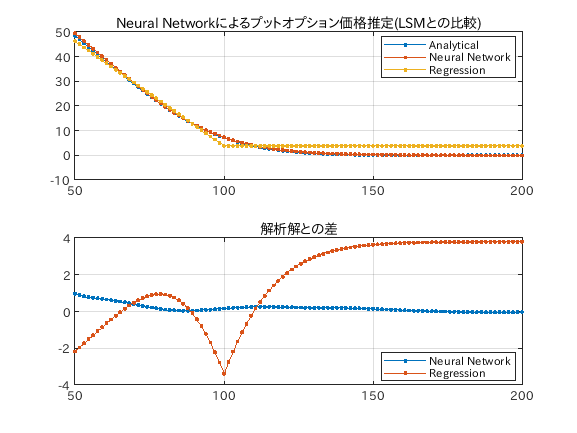

clear; 
%
S0 = 100;
r = 0.06;
sig = 0.4;
%
T = 0.5;
K = 100;

payoffFun = @(St) max(K-St,0); 

dt = 1/12; 
Dft = exp(-r*dt); % one period discount
Nsim = 100000;

% Euler-Maruyama近似でパス生成
Nstep = T/dt; 
paths = S0*ones(Nsim,Nstep+1);
for iloop = 1:Nstep
    paths(:,iloop+1) = paths(:,iloop) + r*paths(:,iloop)*dt + sig*sqrt(dt)*paths(:,iloop).*randn(Nsim,1);
end

dts = (0:Nstep)*dt;

% Neural Networkでの推定
Vop = payoffFun(paths(:,end))'; % Toolboxが行ベクトルを要求しているため
S1 = paths(:,4)'; % ３か月後の株価、toolboxが行ベクトルを要求
net = fitnet(5,'trainlm'); % Deep Learning Toolboxの関数 hidden layerが1層でニューロン数が5とする。
net.trainParam.showWindow = false; 
net = train(net,S1,Vop); % 学習(fitting)
Ss = linspace(50,200,100);
Ves = net(Ss); % 推定値

% regression 
regFun = @(St) [payoffFun(St),ones(size(St,1),1)]; % 回帰計算用の関数設定
X = regFun(paths(:,4)); 
Vreg = regFun(Ss')*((X'*X)\(X'*Vop'));

% analytical 
Vana = calcOptionValue(Ss,r,sig,T-dts(4),K,'optionType','Put');

nfig = 2; 
figure(nfig);subplot(211);plot(Ss,[Vana;Ves;Vreg'],'.-');grid; legend('Analytical','Neural Network','Regression','Location',"best");
title('Neural Networkによるプットオプション価格推定(LSMとの比較)');
figure(nfig);subplot(212);plot(Ss,[Ves-Vana;Vreg'-Vana],'.-');grid; legend('Neural Network','Regression','Location',"best");
title('解析解との差');

ニューロン数を増やしてみる

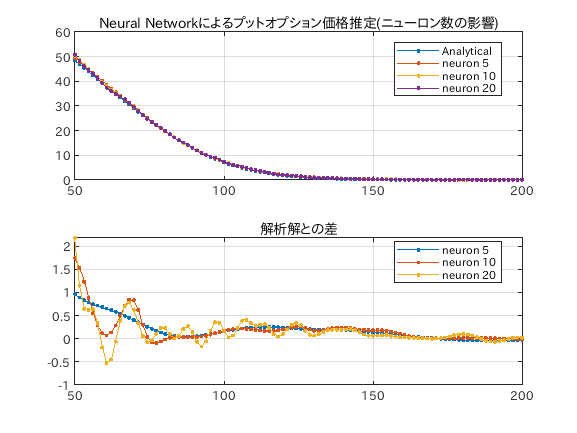

net = fitnet(10,'trainlm'); % Deep Learning Toolboxの関数 hidden layerが1層でニューロン数が10とする。
net.trainParam.showWindow = false; 
net = train(net,S1,Vop); % 学習(fitting)
Ves10 = net(Ss); % 推定値

net = fitnet(20,'trainlm'); % Deep Learning Toolboxの関数 hidden layerが1層でニューロン数が20とする。
net.trainParam.showWindow = false; 
net = train(net,S1,Vop); % 学習(fitting)
Ves20 = net(Ss); % 推定値

nfig =3; 
figure(nfig);subplot(211);plot(Ss,[Vana;Ves;Ves10;Ves20],'.-');grid; legend('Analytical','neuron 5','neuron 10','neuron 20','Location',"best");
title('Neural Networkによるプットオプション価格推定(ニューロン数の影響)');
figure(nfig);subplot(212);plot(Ss,[Ves-Vana;Ves10-Vana;Ves20-Vana],'.-');grid; legend('neuron 5','neuron 10','neuron 20','Location',"best");
title('解析解との差');

Layerを増やしてみる

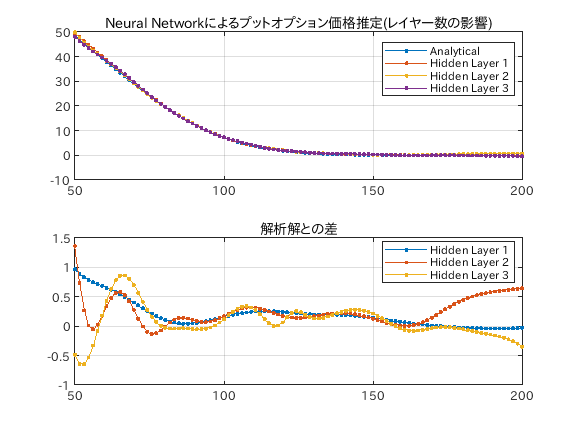

net = fitnet([5 5],'trainlm'); % Deep Learning Toolboxの関数 hidden layerが2層でニューロン数が5とする。
net.trainParam.showWindow = false; 
net = train(net,S1,Vop); % 学習(fitting)
Ves55 = net(Ss); % 推定値

net = fitnet([5 5 5],'trainlm'); % Deep Learning Toolboxの関数 hidden layerが3層でニューロン数が5とする。
net.trainParam.showWindow = false; 
net = train(net,S1,Vop); % 学習(fitting)
Ves555 = net(Ss); % 推定値

nfig = 4; 
figure(nfig);subplot(211);plot(Ss,[Vana;Ves;Ves55;Ves555],'.-');grid; legend('Analytical','Hidden Layer 1','Hidden Layer 2','Hidden Layer 3','Location',"best");
title('Neural Networkによるプットオプション価格推定(レイヤー数の影響)');
figure(nfig);subplot(212);plot(Ss,[Ves-Vana;Ves55-Vana;Ves555-Vana],'.-');grid; legend('Hidden Layer 1','Hidden Layer 2','Hidden Layer 3','Location',"best");
title('解析解との差');

**課題１**

LSM(上方バイアス、下方バイアス）、Rogersの方法においてはsectioningを用いて信頼区間を推定するようにプログラムを書き換えよ。

**課題２**

初期株価を$S_0 = 80,85,90,95,100,105,110,115,120$として二項ツリー、LSM(上方バイアス、下方バイアス）、Rogersの方法での

アメリカンプットオプションの価格を算出して比較せよ。LSMとRogersの方法ではsectioningを用いて99%信頼区間を推定せよ。

Rogersの論文の数値計算結果を以下に示す。


$$\matrix{
S_0 & 80 & 85 & 90 & 95 & 100 & 105 & 110 & 115 & 120 \cr
\text{Tree} & 21.6059 & 18.0374 & 14.9187 & 12.2314 & 9.9458 & 8.0281 & 6.4352 & 5.1265 & 4.0611 \cr
\text{Monte Carlo} & 21.6953 & 18.1008 & 14.9692 & 12.2685 & 9.9703 & 8.0439 & 6.4757 & 5.1363 & 4.0761 
}$$


### ローカル関数

二項ツリーの図を作成するための補助関数

function [ts,vs] = mkDataForBinaryTreeGraph()
    %時間
    ts = [0;1;2;3];

    % パス
    l1 = [0;1;2;3];
    l2 = [0;1;2;1];
    l3 = [0;1;0;-1];
    l4 = [0;-1;-2;-3];
    l5 = [0;-1;-2;-1];
    l6 = [0;-1;0;1];
    % パスを行列でもつ
    vs = [l1,l2,l3,l4,l5,l6];
end

#### 二項ツリーの実装

function v = binomialTree(S0,R,u,d,N,payoffFun,isAmerican)
    %
    arguments
        S0 (1,1) {mustBeReal,mustBePositive}
        R (1,1) {mustBeReal,mustBePositive} % risk freeでの変化率 exp(r \Delta t)
        u (1,1) {mustBeReal,mustBePositive,mustBeGreaterThan(u,R)} % 上昇率
        d (1,1) {mustBeReal,mustBePositive,mustBeLessThan(d,R)} % 下降率
        N (1,1) {mustBeInteger,mustBePositive} % 満期でのステップ数
        payoffFun (1,1) function_handle %ペイオフ関数 R^+ -> R
        isAmerican (1,1) logical % アメリカンオプション(true), ヨーロピアン(false)
    end

    ST = @(j) S0*u.^(N-j).*d.^(j); % 満期での原資産価格の関数
    vmat = arrayfun(payoffFun,ST((0:N)')); % 満期でのオプションペイオフ
    q = (R-d)/(u-d); % リスク中立での上昇確率
    St = @(i,j) S0*u.^(i-(j-1)).*d.^(j-1); % 時点 t_i での原資産価格の関数

    v = binomialTreeImpl(vmat,N-1);

    function rv = binomialTreeImpl(vt,i)
        vi = zeros(i+1,1);
        for j = 1:i+1
            vi(j,1) = (q*vt(j,1)+(1-q)*vt(j+1,1))/R; 
            if and(isAmerican,gt(i,0))
                vi(j,1) = max(vi(j,1),payoffFun(St(i,j)));
            end
        end
        if isequal(i,0)
            rv = vi; 
        else
            rv = binomialTreeImpl(vi,i-1); 
        end
    end

end

#### LSMの実装:アメリカンオプション（下方バイアス）

function v = lsm(spath,payoffFun,Dft,regFun)
    arguments
        spath (:,:) {mustBeReal} % 原資産のシミュレーションパス
        payoffFun (1,1) function_handle % オプションのペイオフ関数
        Dft (1,1) {mustBeReal, mustBePositive} % 1区間での割引
        regFun (1,1) function_handle % 回帰関数を返す関数
    end

    nStep = size(spath,2); % 時間ステップ数
    mkSt = @(eid) spath(:,nStep-eid); 

    v = lsmImpl(payoffFun(mkSt(0)),1); 

    function rv = lsmImpl(Vp,iStep)
        if isequal(iStep,nStep-1)
            rv = Vp.*Dft;
        else
            St = mkSt(iStep);
            X = regFun(St);
            Vp = Vp.*Dft; 

            coeff = (X'*X)\(X'*Vp);
            Vtmp = X*coeff;

            id = find(le(Vtmp,payoffFun(St)));
            Vp(id) = payoffFun(St(id));

            rv = lsmImpl(Vp,iStep+1);
        end
    end
end

#### LSMの実装:アメリカンオプション（上方バイアス）

function v = lsmUpper(spath,payoffFun,Dft,regFun)
    arguments
        spath (:,:) {mustBeReal} % 原資産のシミュレーションパス
        payoffFun (1,1) function_handle % オプションのペイオフ関数
        Dft (1,1) {mustBeReal, mustBePositive} % 1区間での割引
        regFun (1,1) function_handle % 回帰関数を返す関数
    end

    nStep = size(spath,2);
    mkSt = @(eid) spath(:,nStep-eid);

    v = lsmImpl(payoffFun(mkSt(0)),1); 

    function rv = lsmImpl(Vp,iStep)
        if isequal(iStep,nStep-1)
            rv = Vp.*Dft;
        else
            St = mkSt(iStep);
            X = regFun(St);
            Vp = Vp.*Dft; 
            
            coeff = (X'*X)\(X'*Vp);
            Vtmp = X*coeff;

            id = find(le(Vtmp,payoffFun(St)));
            Vp(id) = payoffFun(St(id));
            
            id = find(gt(Vtmp,payoffFun(St)));
            Vp(id) = Vtmp(id,:);

            rv = lsmImpl(Vp,iStep+1);
        end
    end

end

### LSM/Neural Networkの実装:アメリカンオプション（Duality approach ）

function mt = lsmNNForDuality(spath,payoffFun,Dft,regFun,options)
    arguments
        spath (:,:) {mustBeReal}
        payoffFun (1,1) function_handle
        Dft (1,1) {mustBeReal, mustBePositive}
        regFun (1,1) function_handle
        options.method {mustBeMember(options.method,{'LSM','NN'})} = 'LSM'
    end

    [Nsim,nStep] = size(spath);
    mkSt = @(eid) spath(:,nStep-eid);

    rvi = zeros(Nsim,nStep);
    rvi(:,end) = payoffFun(mkSt(0));
    rvci = rvi; 
    
    mt = lsmImpl(payoffFun(mkSt(0)),rvi,rvci,1); 
    
    function rmt = lsmImpl(Vp,rvi,rvci,iStep)
        if isequal(iStep,nStep-1)
            rvi(:,nStep-iStep) = mean(Vp.*Dft);
            rvci(:,nStep-iStep) = rvi(:,nStep-iStep); 
          
            rmt = zeros(size(rvi)); 
            rmt(:,1) = rvi(:,1);
            for iloop = 2:size(rvi,2)
                rmt(:,iloop) = rmt(:,iloop-1) + rvi(:,iloop) - rvci(:,iloop-1); 
            end
            rmt = rmt - rvi(:,1); 
        else
            Vp = Vp.*Dft; 
            St = mkSt(iStep);
            
            switch options.method
                case "LSM"
                    X = regFun(St);
                    coeff = (X'*X)\(X'*Vp);
                    Vtmp = X*coeff; 
                case "NN"
                    net = fitnet(5,'trainlm');
                    net.trainParam.showWindow = false; 
                    net = train(net,St',Vp');
                    Vtmp = (net(St'))'; 
                otherwise
                    error('unexpected method');
            end

            id = find(le(Vtmp,payoffFun(St)));
            Vp(id) = payoffFun(St(id));

            id = find(gt(Vtmp,payoffFun(St)));
            Vp(id) = Vtmp(id);

            rvi(:,nStep-iStep) = Vp*(Dft^(nStep-iStep)); 
            rvci(:,nStep-iStep) = Vtmp*(Dft^(nStep-iStep)); 

            rmt = lsmImpl(Vp,rvi,rvci,iStep+1);
        end
    end
end

put option pricer for Rogers method

function v = calcOptionValue(St,r,sig,T,K,options)
    arguments
        St (:,:) {mustBeReal,mustBePositive}
        r (1,1) {mustBeReal}
        sig (1,1) {mustBeReal,mustBePositive}
        T (1,:) {mustBeReal,mustBeNonnegative}
        K (1,1) {mustBeReal,mustBePositive}
        options.optionType {mustBeMember(options.optionType,{'Call','Put'})} = 'Put'
    end
    d1 = (log(St/K)+r*T)./(sig*sqrt(T)) + 1/2*sig*sqrt(T);
    d2 = d1 - sig*sqrt(T);
    Nd1 = normcdf(d1); 
    Nd2 = normcdf(d2);

    callValue = St.*Nd1 - K*exp(-r*T).*Nd2;
    putValue = callValue - St + K*exp(-r*T);

    switch options.optionType
        case 'Call'
            v = callValue;
        case 'Put'
            v = putValue;
        otherwise
            error('unexpected option type');
    end

end